#### Exercicios metodo de Euler

#### 1)

clear all
syms y(t)
f=@(t,y) y+exp(t)

f = function_handle with value:
    @(t,y)y+exp(t)


n=100

n =    100


h=0.01

h =    0.010000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n];
y=[1,n];
t(1)=t0;
y(1)=y0;
hold on
for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    disp([i,t(i+1),y(i+1)])
end

   1.000000000000000   1.010000000000000   0.128182818284590

   2.000000000000000   1.020000000000000   0.156920656617606

   3.000000000000000   1.030000000000000   0.186221810823425

   4.000000000000000   1.040000000000000   0.216094687278650

   5.000000000000000   1.050000000000000   0.246547804294952

   6.000000000000000   1.060000000000000   0.277589793518533

   7.000000000000000   1.070000000000000   0.309229401346398

   8.000000000000000   1.080000000000000   0.341475490359632

   9.000000000000000   1.090000000000000   0.374337040773883

  10.000000000000000   1.100000000000000   0.407823151907253

  11.000000000000000   1.110000000000000   0.441943043665790

  12.000000000000000   1.120000000000000   0.476706058046804

  13.000000000000000   1.130000000000000   0.512121660660202

  14.000000000000000   1.140000000000000   0.548199442268052

  15.000000000000000   1.150000000000000   0.584949120342594

  16.000000000000000   1.160000000000000   0.622380540642917

  17.000

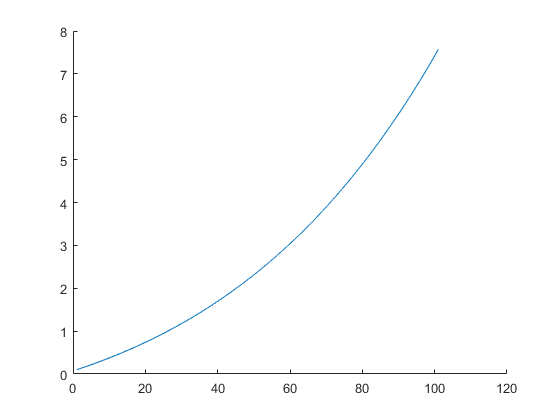

plot(y)
hold off

syms y(t)
edo1=diff(y(t),t)==y+exp(t)

$$edo1(t) = \frac{\partial }{\partial t}y\left(t\right)={\mathrm{e}}^{t}+y\left(t\right)$$

a=dsolve(edo1,y(1)==0.1)

$$a = {\mathrm{e}}^{t}\,\left(\frac{{\mathrm{e}}^{-1}}{10}-1\right)+t\,{\mathrm{e}}^{t}$$

simplify(a)

$$ans = {\mathrm{e}}^{t-1}\,\left(t\,\mathrm{e}-\mathrm{e}+\frac{1}{10}\right)$$

clear all
syms y(t)
f=@(t,y) y+exp(t)

f = function_handle with value:
    @(t,y)y+exp(t)


n=100

n =    100


h=0.01

h =    0.010000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n];
y=[1,n];
t(1)=t0;
y(1)=y0;
phi=@(t) exp(t-1).*(t.*exp(1.0)-exp(1.0)+0.1);
disp('i t[i] y[i] phi(t[i]) erro')

i t[i] y[i] phi(t[i]) erro


for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    erro=abs(y(i+1)-phi(t(i+1)));
    disp([i,t(i+1),y(i+1),phi(t(i+1)),erro])
end

   1.000000000000000   1.010000000000000   0.128182818284590   0.128461026858586   0.000278208573996

   2.000000000000000   1.020000000000000   0.156920656617606   0.157484029281962   0.000563372664356

   3.000000000000000   1.030000000000000   0.186221810823425   0.187077428436324   0.000855617612899

   4.000000000000000   1.040000000000000   0.216094687278650   0.217249757993301   0.001155070714652

   5.000000000000000   1.050000000000000   0.246547804294952   0.248009665540761   0.001461861245809

   6.000000000000000   1.060000000000000   0.277589793518533   0.279365914010614   0.001776120492081

   7.000000000000000   1.070000000000000   0.309229401346398   0.311327383123812   0.002097981777414

   8.000000000000000   1.080000000000000   0.341475490359632   0.343903070852738   0.002427580493106

   9.000000000000000   1.090000000000000   0.374337040773883   0.377102094901197   0.002765054127314

  10.000000000000000   1.100000000000000   0.407823151907253   0.410933694202208  

phi=@(t) exp(t-1).*(t.*exp(1.0)-exp(1.0)+0.1)

phi = function_handle with value:
    @(t)exp(t-1).*(t.*exp(1.0)-exp(1.0)+0.1)


erro_absoluto=abs(y(101)-phi(2.0))

erro_absoluto =    0.092825681320442


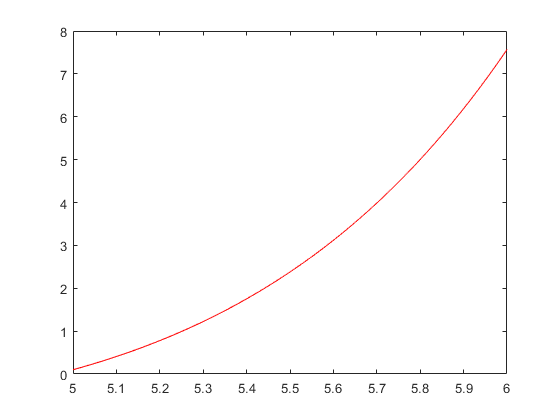


plot(5:0.01:6,y,'color',[1.0,0.0,0.0])

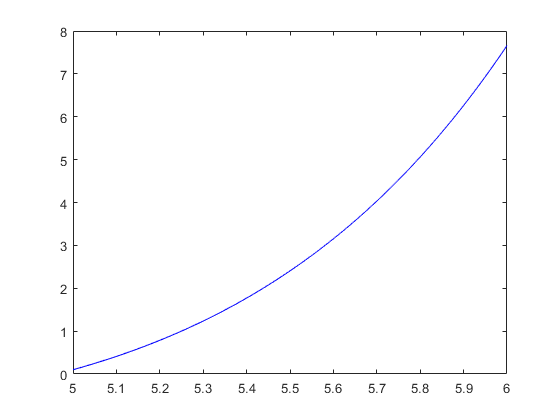

plot(5:0.01:6,phi(t),'color',[0.0,0.0,1.0])
hold off

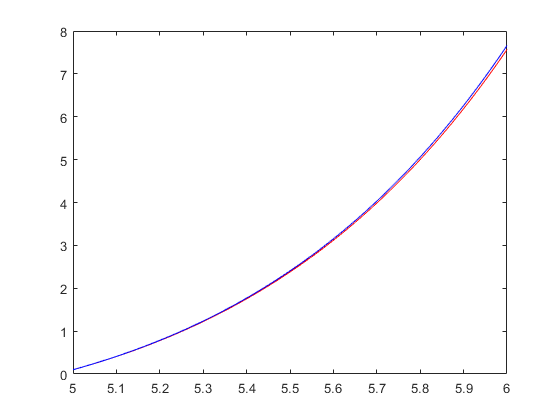

hold on
plot(5:0.01:6,y,'color',[1.0,0.0,0.0])
plot(5:0.01:6,phi(t),'color',[0.0,0.0,1.0])
hold off

clear all
syms y(t)
f=@(y,t) y+exp(t)

f = function_handle with value:
    @(y,t)y+exp(t)


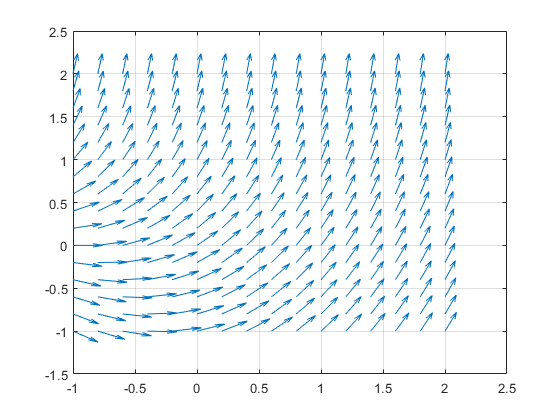

[t,y]=meshgrid(-1:0.2:2,-1:0.2:2);
u=ones(length(t));
v=f(t,y);
l=sqrt(1+v.^2);
quiver(t,y,u./l,v./l)
grid on